clear all; close all;
ones([1, 2]);

time = 0 : 0.01 : 10;
x0 = [0;0;0];
x = zeros(length(time), 3);

Earth;
F = [0; 0; 0];
a = F./(m*w0*R0)

a =      0
     0
     0



r = sqrt((x(1) + 1)^2 + x(2)^2 + x(3)^2);
dx(1) = x(4);
dx(2) = x(5);
dx(3) = x(6);
dx(4) = 2*x(5) + (1 + x(1))*(1 - r^(-3)) + a(1);
dx(5) = -2*x(4) + x(2)*(1 - r^(-3)) + a(2);
dx(6) = -x(3)*r^(-3) + a(3);


u = [0 0 0];
MDNS = 100;
size(u)

ans =      1     3



%Polozenie poczatkowe wzgledem Ziemi
Rz = 6.37314*1e6;
x0z = [7e5; 0; 0] + Rz;

v0z = [0 ;7.9196 *1e3; 0];
x0z = [x0z; v0z];

[x0sk, v0sk] = r2x_transform(x0z(1:3), x0z(4:6), 0)

x0sk =    -0.8326
    0.1509
    0.1509


v0sk =     0.1509
    2.4106
         0


tau = [10]';

Rz = 6.37314*1e6;
R0 = Rz + 7e5;%4.2242e7;
x0 = [R0;0;0];

%rhat = norm(x0);
%r = x0/rhat;

G = 6.67e-11;
M = 5.98e24;
    
v0 = sqrt(G*M/R0) * [0; 0; 1];



[x0sk, v0sk] = r2x_transform(x0, v0, 0);
x0 = [x0sk; v0sk]

x0 =    -0.8326
         0
         0
         0
   -0.1674
    2.4445


% x0 = [0;0;0;0;0;0]

[t,x,~,~] = get_tx(tau,u,x0,MDNS);
t1=t*86400/(2*pi);

xorb=zeros(length(t),6);
for k=1:length(t)
    [xEarth, vEarth] = x2r_transform(x(k, 1:3)', 0, t1(k));
    xorb(k,:)= [xEarth; vEarth];
end 


figure;
% plot3(xorb(:,1), xorb(:,2), xorb(:,3))
printOrbit(xorb(:,1), xorb(:,2), xorb(:,3));

grid on;





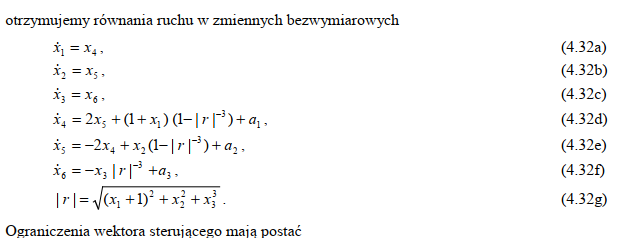

clear;close all;
nu=20;tf=1;umax=1;umin=-1;
tau=(tf/nu)*[1:nu]';uopt=zeros(nu,3);
Rz = 6.37314*1e6;
R0 = Rz + 7e5;%4.2242e7;
x0 = [R0;0;0];
G = 6.67e-11;
M = 5.98e24;
v0 = sqrt(G*M/R0) * [0; 0; 1];
[x0sk, v0sk] = r2x_transform(x0, v0, 0);

% Definicje początkowe
x0 = [x0sk; v0sk];            % Stan początkowy (pozycja + prędkość)
xf = [0; 0; 0; 0; 0; 0];      % Stan końcowy (zero)
W = 0 * eye(6);               % Waga w funkcji kosztu (tu zerowa)
MDNS = 1e3;                   % Ilość kroków dyskretyzacji

% Definicja funkcji kosztu
qh = @(uopt) cost_fun_s(uopt, tau, x0, xf, W, MDNS);

% Parametry optymalizacji
nu = length(uopt);            % Liczba zmiennych sterowania
LB = -ones(nu,1);             % Dolne ograniczenia na uopt
UB = ones(nu,1);              % Górne ograniczenia na uopt

% Opcje dla fmincon
options = optimoptions('fmincon');
options.SpecifyObjectiveGradient = false;
options.Display = 'iter';
options.Algorithm = 'interior-point';

% Rozwiązanie problemu optymalizacji
uopt = fmincon(qh, uopt, [], [], [], [], LB, UB, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      61    1.000000e+00    0.000e+00    0.000e+00

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<


% Symulacja trajektorii
[t, x, uk, nseg] = get_tx_s(tau, uopt, x0, MDNS);

% Liczenie współczynnika adjoint (co-state)
pf = [-W * (x(end,1:end)' - xf)];
p = rk4p_s(pf, t, x, uk);

Unary operator '-' is not supported for operand of type 'function_handle'.

Error in rk4p_s (line 29)
        dp1   = - prhs_s(tt, x(k, :)', uk(k+1, :)', ptmp);


% Liczenie wartości hamiltonianu
hmax = get_hmax(t, p, x, uk);

% Rysowanie wyników
figure;

subplot(2,1,1);
h = plot(t, [x(:,1), x(:,2)/10, x(:,3)]);
set(h, 'LineWidth', 2);
title('Trajektoria stanu');
legend('x_1', 'x_2/10', 'x_3');
grid on;

subplot(2,1,2);
hold on;
h1 = plot(t, hmax);
h2 = stairs(t, uk);
set([h1; h2], 'LineWidth', 2);
axis([0 t(end) -1.1 1.1]);
title('Sterowanie i Hamiltonian');
legend('h_{max}', 'Sterowanie u_k');
grid on;
hold off;


clear;close all;tau=[.2 .3 .4 .5]';u=1.0*[1;-1;1;1];
x0=[0;0;0;0];xf=[pi;0;0];W=1000*eye(3);MDNS=1e3;
ep=1e-9;gnum=zeros(length(u),1);
[q,g]=cost_fun_s(u,tau,x0,xf,W,MDNS);
for k=1:length(tau)
ei=zeros(length(u),1);ei(k)=1;
up=u+ei*ep;um=u-ei*ep;
fp=cost_fun_s(up,tau,x0,xf,W,MDNS);
fm=cost_fun_s(um,tau,x0,xf,W,MDNS);
gnum(k)=(fp-fm)/(2*ep);
end
%porownanie g - r. sprz., gnum - rozn.
[g';gnum']